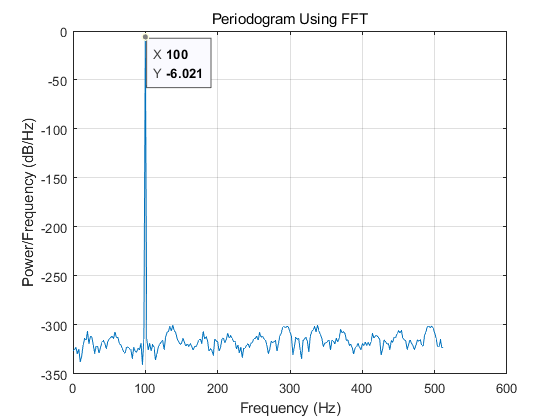

rng default
Fs = 1024;
t = 0:1/Fs:1-1/Fs;
x = cos(2*pi*100*t) ;
N = 512;
xdft = fft(x,N);
xdft = xdft(1:N/2+1);
psdx = (1/(N*Fs)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/N:Fs/2;

plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')



b = hz2bark([20,8000]);
       barkVect = linspace(b(1),b(2),32);
       hzVect = bark2hz(barkVect);
       plot(barkVect,hzVect,'o')
       title('Bark vs Hz')
       xlabel('Bark')
       ylabel('Hz')
       grid on